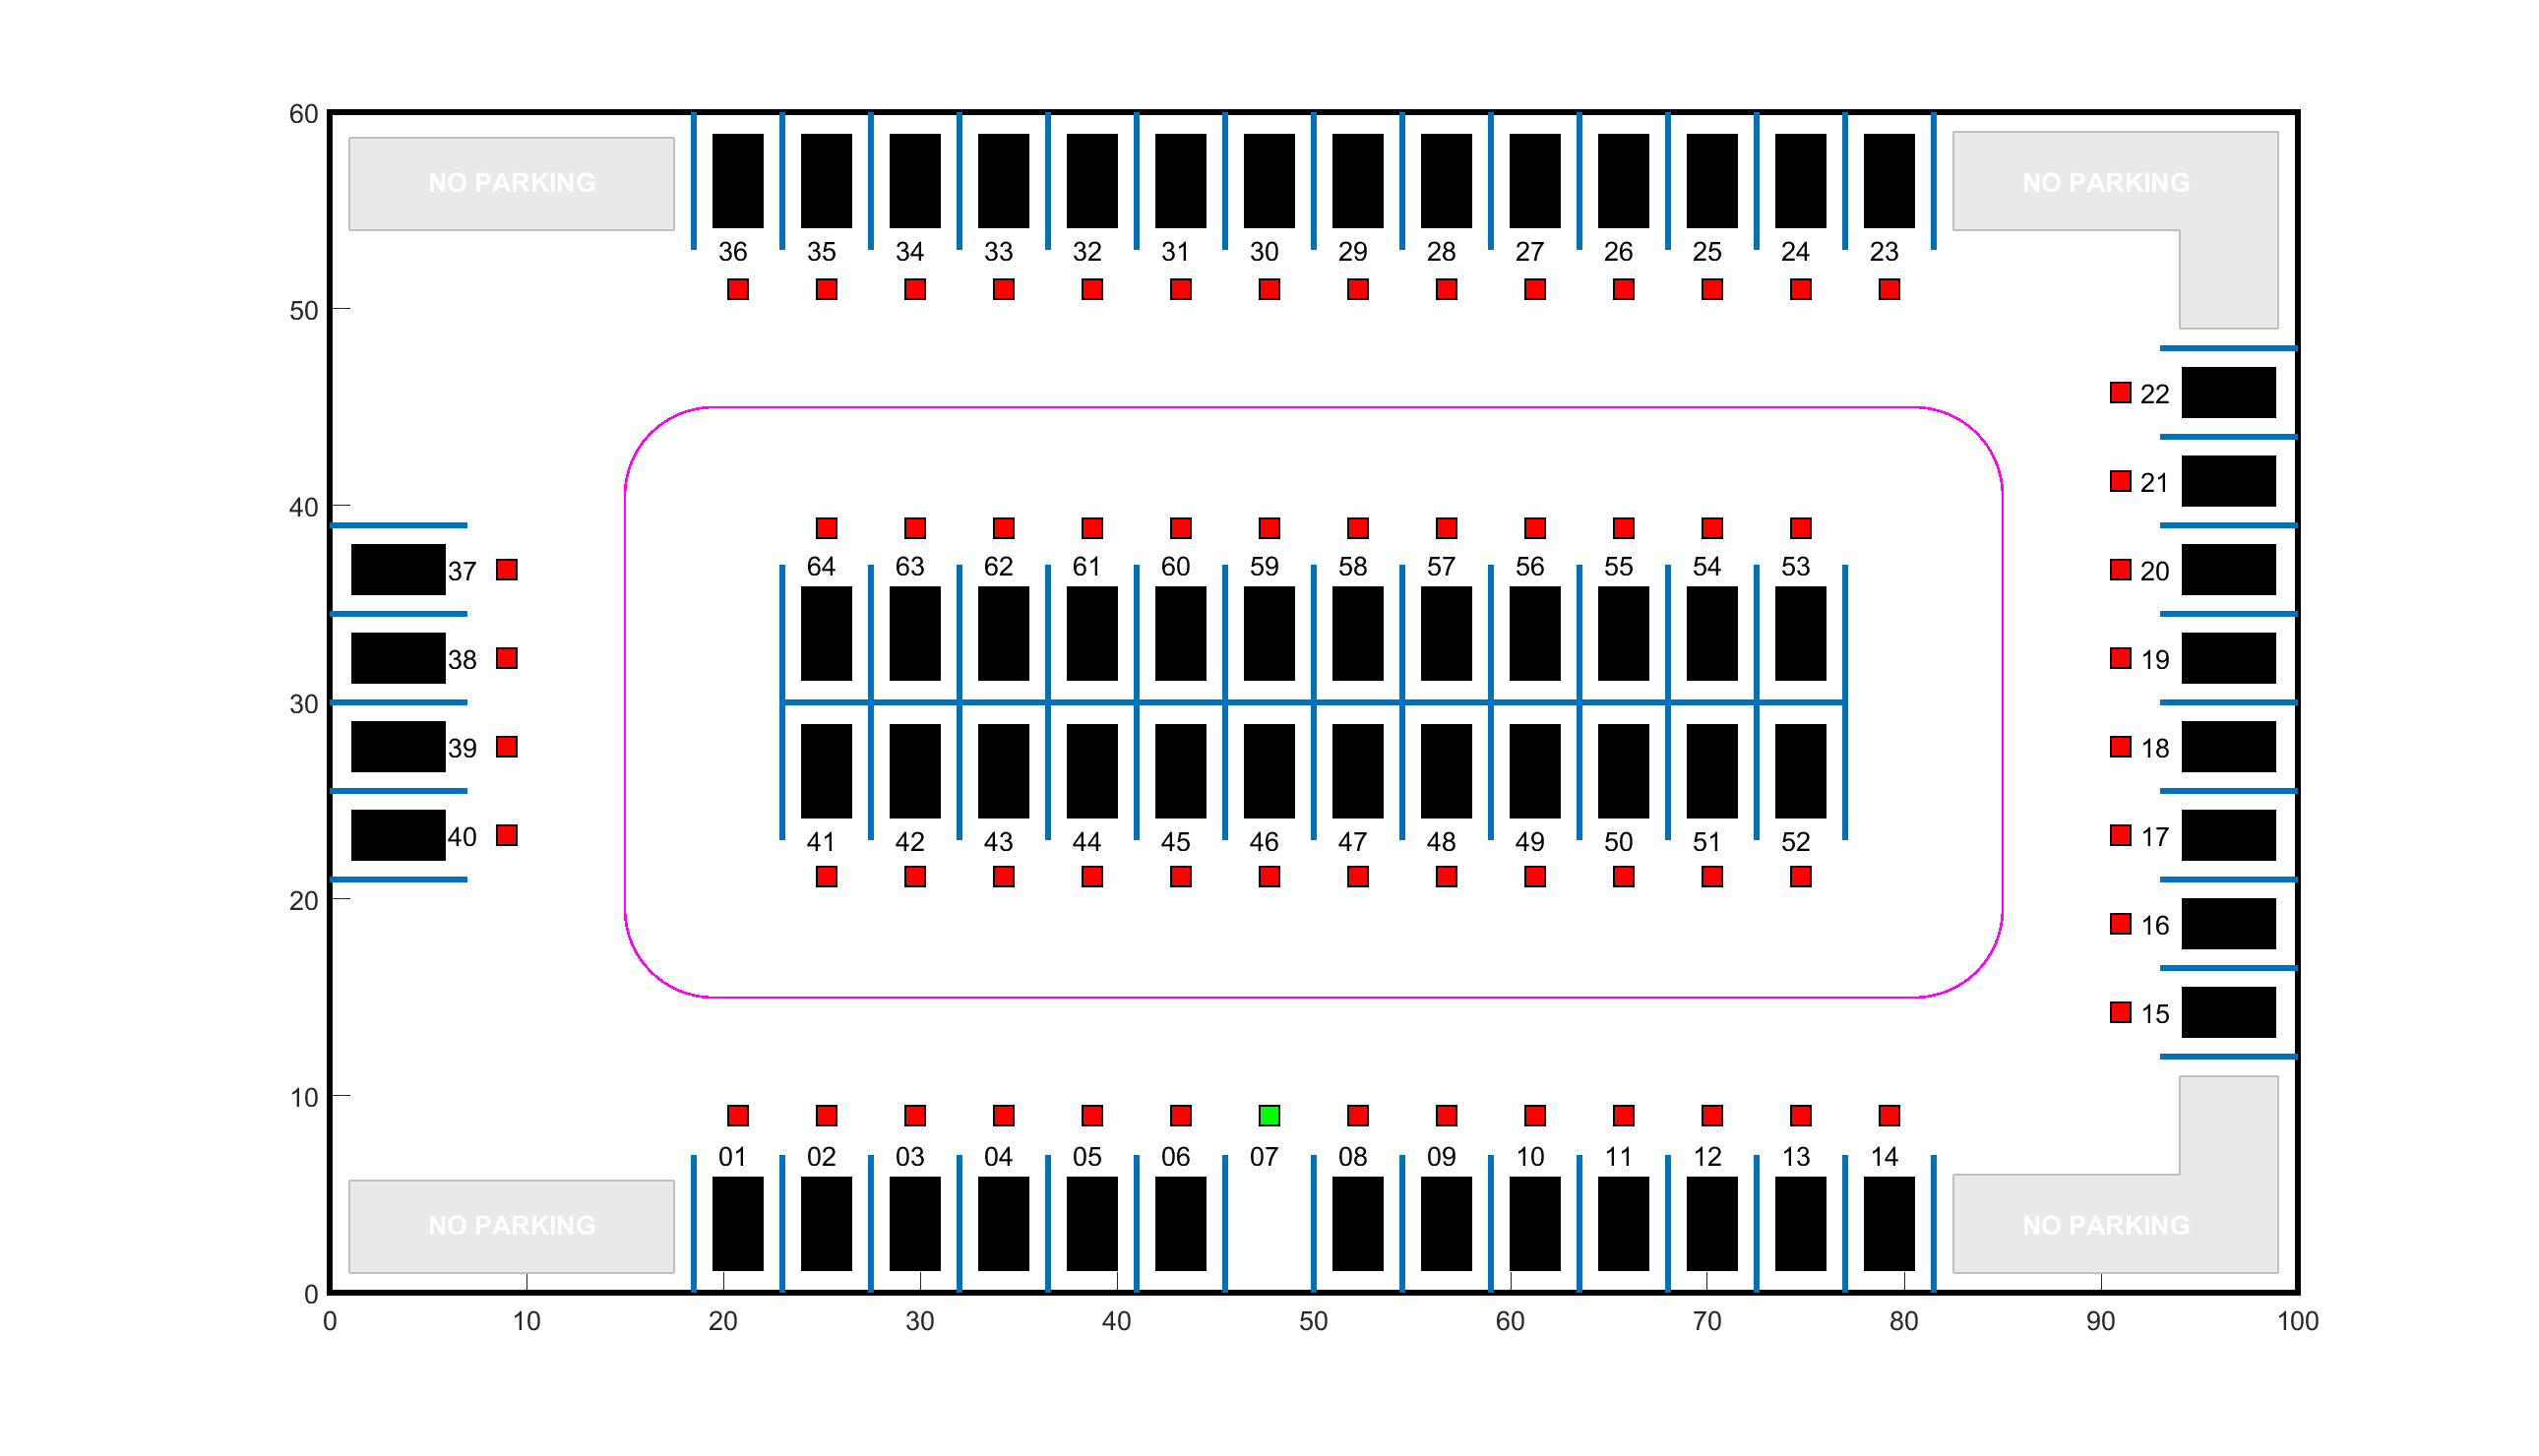

freeSpotIdx = 7;
map = ParkingLot(freeSpotIdx);


egoInitialPose = [20, 15, 0];
egoTargetPose = createTargetPose(map,freeSpotIdx)

egoTargetPose =    47.7500    4.9000   -1.5708




autoParkingValetParams
mdl = "rlAutoParkingValet";
open_system(mdl)
createMPCForParking

numObservations = 16

numObservations = 16

obsInfo = rlNumericSpec([numObservations 1]);
obsInfo.Name = "observations";

obsInfo = rlNumericSpec([numObservations 1]);
obsInfo.Name = "observations";
numActions = 1

numActions = 1

actInfo = rlNumericSpec([numActions 1],LowerLimit=-1,UpperLimit=1);
actInfo.Name = "actions";


blk = mdl + "/RL Controller/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);
env.ResetFcn = @autoParkingValetResetFcn;
%Create Agent
rng(0)
% Input untuk state
statePath = [
    featureInputLayer(numObservations, Name="StateInLyr")
    fullyConnectedLayer(128, Name="fc1")
];
% Input untuk action
actionPath = [
    featureInputLayer(numActions, Name="ActionInLyr")
    fullyConnectedLayer(128,Name="fc2")
];

% Jalur gabungan setelah state dan action digabungkan
commonPath = [
    concatenationLayer(1,2,"Name","concat")
    reluLayer(Name="relu1")
    fullyConnectedLayer(128, Name="fc3")  % Layer ketiga dengan 128 neuron
    reluLayer(Name="relu2")
    fullyConnectedLayer(1, Name="QValue")  % Output nilai Q
];

% === Membuat critic pertama ===
criticNet1 = layerGraph(statePath);
criticNet1 = addLayers(criticNet1, actionPath);
criticNet1 = addLayers(criticNet1, commonPath);

criticNet1 = connectLayers(criticNet1, "fc1", "concat/in1");
criticNet1 = connectLayers(criticNet1, "fc2", "concat/in2");

criticNet1 = dlnetwork(criticNet1)

criticNet1 =   dlnetwork with properties:

         Layers: [9×1 nnet.cnn.layer.Layer]
    Connections: [8×2 table]
     Learnables: [8×3 table]
          State: [0×3 table]
     InputNames: {'StateInLyr'  'ActionInLyr'}
    OutputNames: {'QValue'}
    Initialized: 1

  View summary with summary.


%analyzeNetwork(criticNet1)
% === Membuat critic kedua (struktur sama, tapi parameter berbeda) ===
criticNet2 = layerGraph(statePath);               % buat ulang dari awal
criticNet2 = addLayers(criticNet2, actionPath);   % tambahkan kembali actionPath
criticNet2 = addLayers(criticNet2, commonPath);   % gunakan struktur yang sama

criticNet2 = connectLayers(criticNet2, "fc1", "concat/in1");
criticNet2 = connectLayers(criticNet2, "fc2", "concat/in2");


criticNet2 = dlnetwork(criticNet2)             % ini akan punya bobot yang berbeda dari criticNet1

criticNet2 =   dlnetwork with properties:

         Layers: [9×1 nnet.cnn.layer.Layer]
    Connections: [8×2 table]
     Learnables: [8×3 table]
          State: [0×3 table]
     InputNames: {'StateInLyr'  'ActionInLyr'}
    OutputNames: {'QValue'}
    Initialized: 1

  View summary with summary.


%analyzeNetwork(criticNet2)


% Buat fungsi Q-value untuk SAC
critic1 = rlQValueFunction(criticNet1, obsInfo, actInfo, ...
    ObservationInputNames="StateInLyr", ActionInputNames="ActionInLyr");

critic2 = rlQValueFunction(criticNet2, obsInfo, actInfo, ...
    ObservationInputNames="StateInLyr", ActionInputNames="ActionInLyr");

isequal(critic1, critic2)

ans = logical
   0


% Buat jaringan dasar
actorNet = [
    featureInputLayer(numObservations, Name="input")
    fullyConnectedLayer(128, Name="fc1")  % Tambah layer dengan 512 neuron
    reluLayer(Name="relu1")
    fullyConnectedLayer(128, Name="fc2")
    reluLayer(Name="relu2")
];

meanPath = [
    fullyConnectedLayer(numActions, Name="meanFC")
    tanhLayer(Name="meanLayer")
];

stdPath = [
    fullyConnectedLayer(numActions, Name="stdFC")
    softplusLayer(Name="stdLayer")
];

% Buat layerGraph
actorLG = layerGraph(actorNet);
actorLG = addLayers(actorLG, meanPath);
actorLG = addLayers(actorLG, stdPath);

% **Sambungkan hidden layer terakhir ke mean dan std path**
actorLG = connectLayers(actorLG, "relu2", "meanFC");  
actorLG = connectLayers(actorLG, "relu2", "stdFC");

% Buat jaringan dlnetwork
actordlNet = dlnetwork(actorLG);
%analyzeNetwork(actordlNet)

% Definisikan actor untuk reinforcement learning
actor = rlContinuousGaussianActor(actordlNet, obsInfo, actInfo, ...
    ActionMeanOutputNames="meanLayer", ...
    ActionStandardDeviationOutputNames="stdLayer" ...
);

criticOptions = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=1);
actorOptions = rlOptimizerOptions( ...
    LearnRate=2e-4, ...
    GradientThreshold=1);

agentOpts = rlSACAgentOptions(...
    SampleTime=Ts,...
    TargetSmoothFactor=0.05,...
    ExperienceBufferLength=1e6,...
    MiniBatchSize=64,...
    CriticOptimizerOptions=criticOptions, ...
    ActorOptimizerOptions=actorOptions, ...
    EntropyWeightOptions=EntropyWeightOptions(LearnRate=5e-4),...
    DiscountFactor=0.998);

agent = rlSACAgent(actor,[critic1 critic2],agentOpts);

%Training Agent
trainOpts = rlTrainingOptions(...
    MaxEpisodes=10000,...
    MaxStepsPerEpisode=200,...
    ScoreAveragingWindowLength=200,...
    Plots="training-progress",...
    StopTrainingCriteria="EpisodeCount",...
    StopTrainingValue=700, ...
    Verbose=true);

doTraining = false;
if doTraining
    trainingResult = train(agent,env,trainOpts);
    save("TrainingResult.mat", "agent");
else
    load("hrlAutoParkingValetAgent.mat", "agent");
end

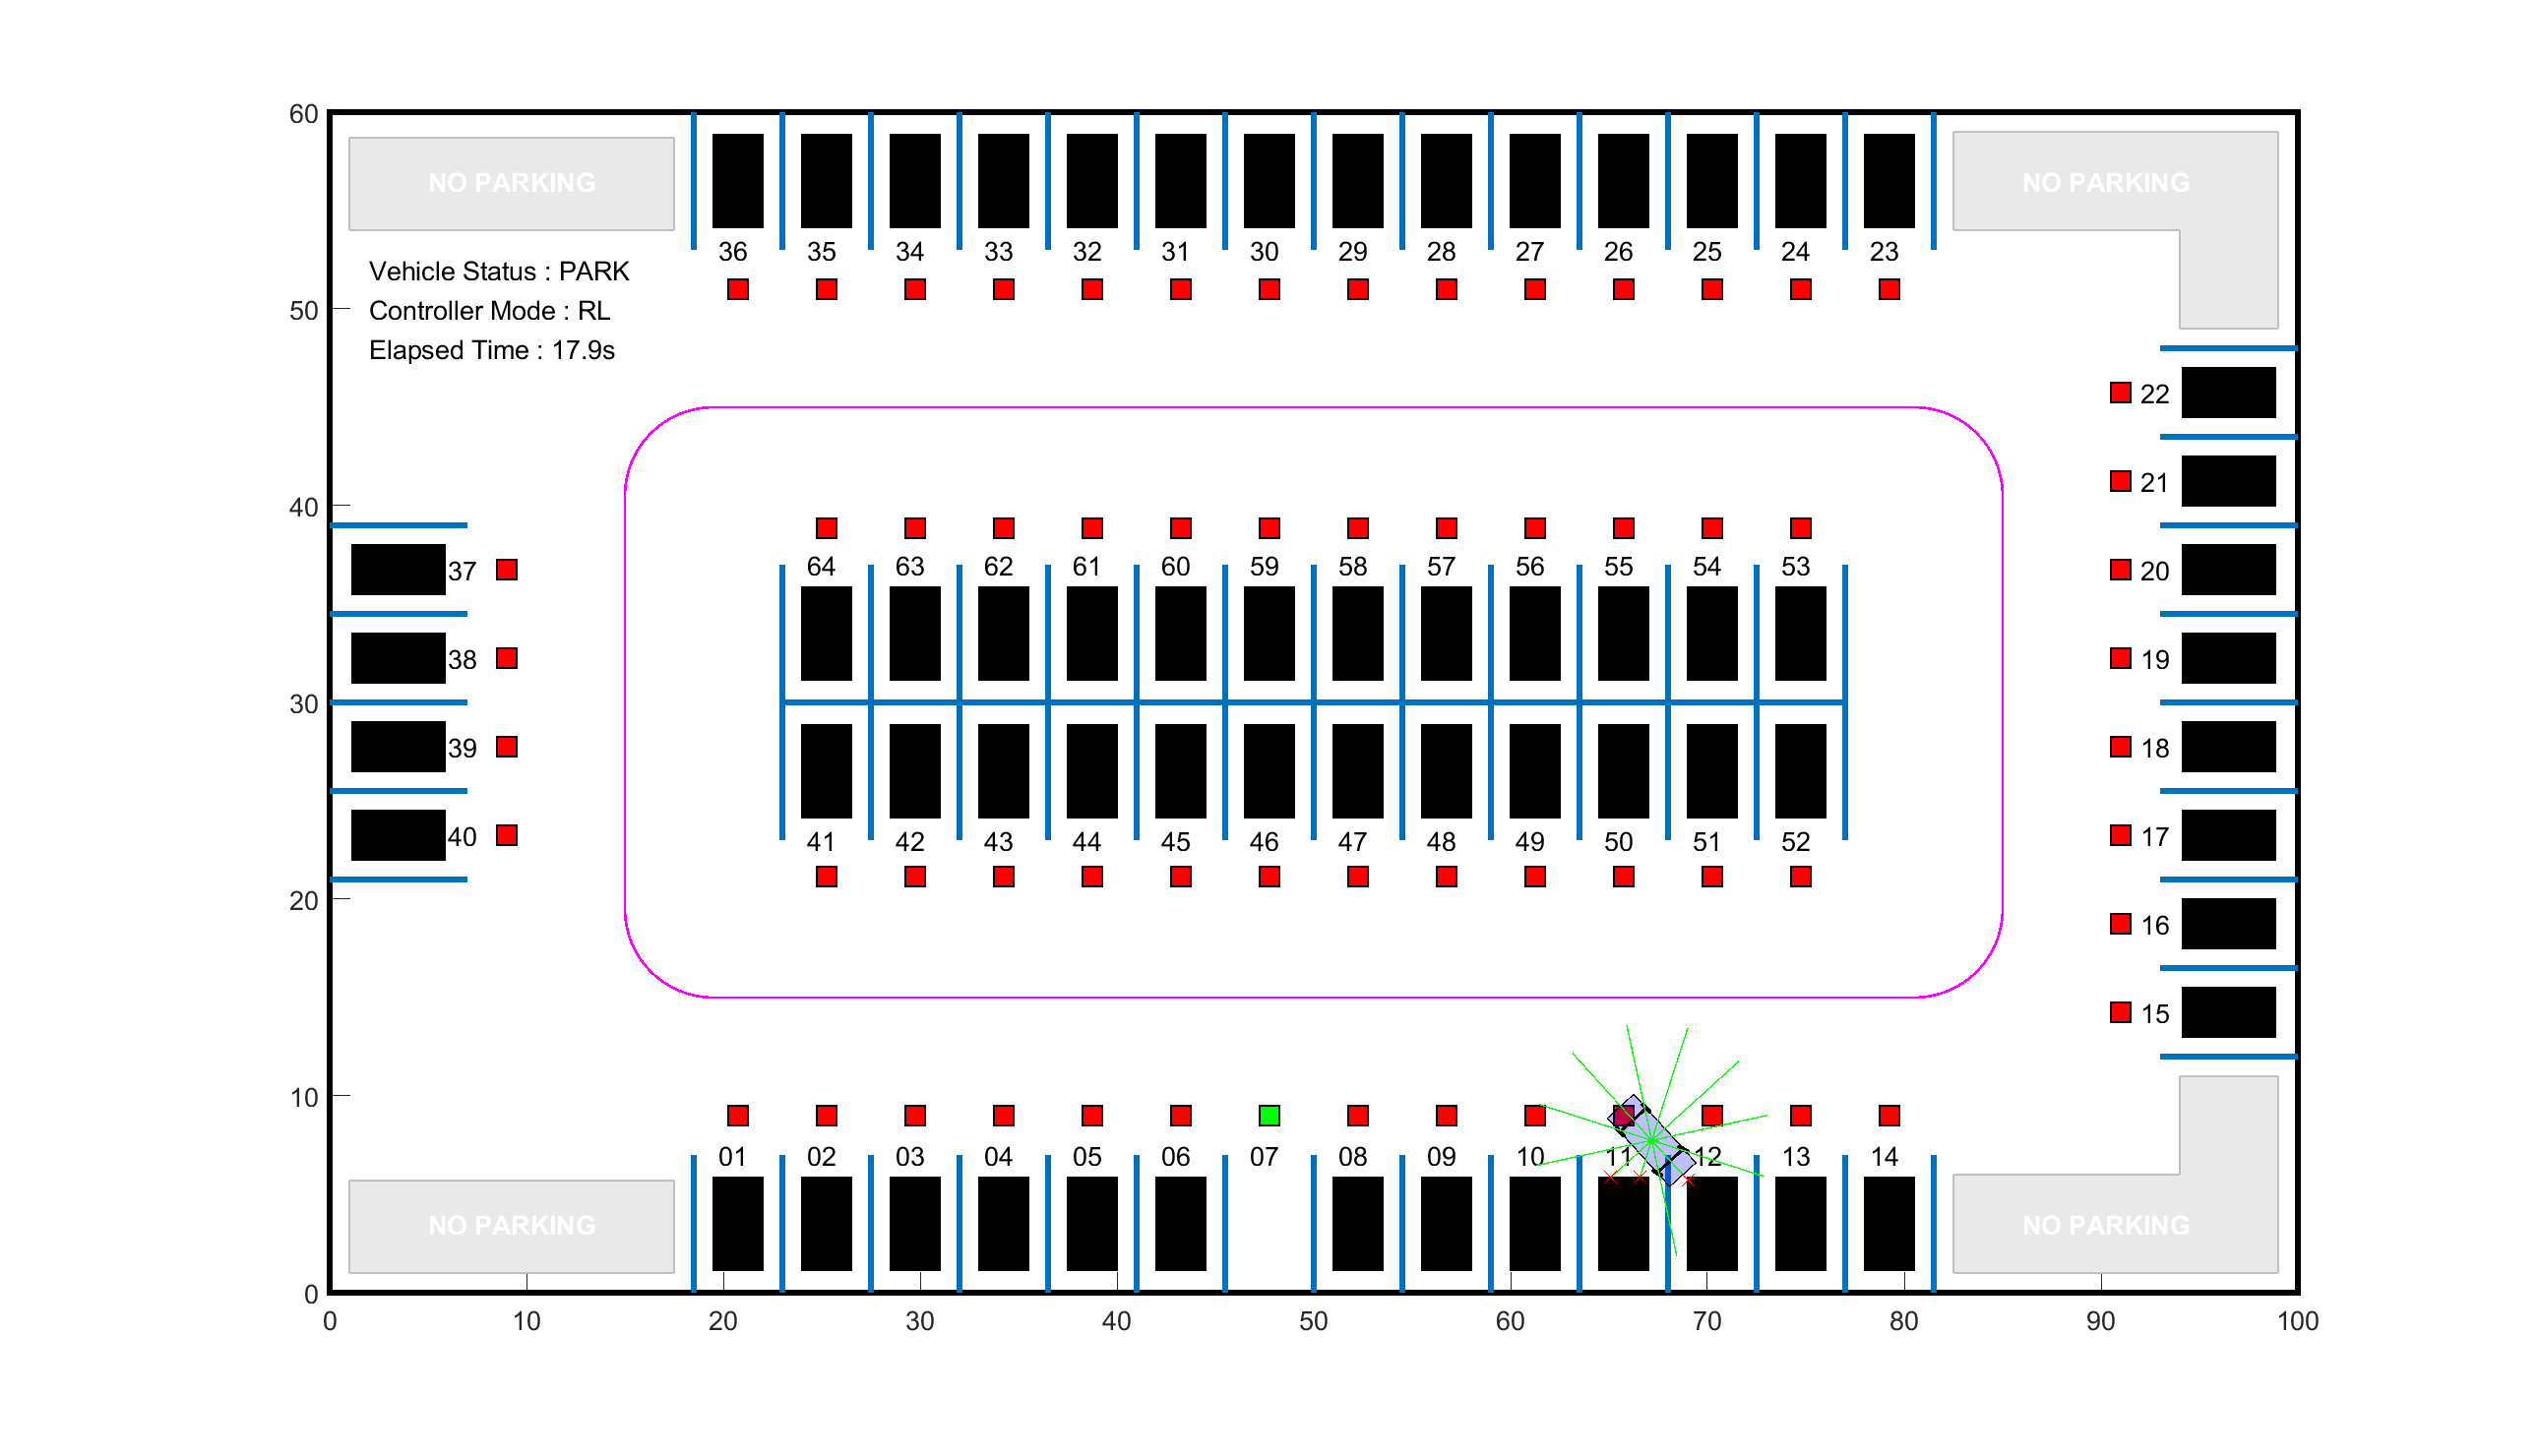

ans =   Simulink.SimulationOutput:

                   tout: [203x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



sim(mdl)

open_system(mdl + "/Ego Vehicle Model/Ego Vehicle Pose");
% Simpan hasil training: Episode, Episode Reward, Average Reward, dan Q0
numEpisodes = numel(trainingResult.EpisodeIndex);  % Ambil jumlah episode

Unable to resolve the name 'trainingResult.EpisodeIndex'.

episodeReward = trainingResult.EpisodeReward;      % Episode reward
averageReward = trainingResult.AverageReward;      % Average reward
episodeQ0 = trainingResult.EpisodeQ0;              % Q0 di setiap episode
step1 = trainingResult.EpisodeSteps;
step2 = trainingResult.TotalAgentSteps;

% Buat tabel untuk menyimpan data
rewardTable = table((1:numEpisodes)', episodeReward(:), averageReward(:), episodeQ0(:), step1(:), step2(:),...
                    'VariableNames', {'Episode', 'EpisodeReward', 'AverageReward', 'EpisodeQ0', 'EpisodeSteps', 'TotalAgentSteps'});

% Simpan ke file Excel
writetable(rewardTable, 'TrainingResultsSACOriginalFix.xlsx');

% Tampilkan tabel di Command Window
disp('Reward Table:');
disp(rewardTable);
